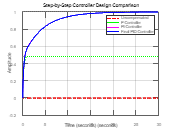

% MATLAB Code for Chapter IV: Manual PID Controller Tuning
% ---------------------------------------------------------
% This script demonstrates a structured manual tuning process.
% This version contains the correction for the 'SettlingTime' field name.

% Clear workspace, command window, and close all figures
clear; clc; close all;

% --- 1. Define the Original System (Plant) ---
num_ol = [-10.07];
den_ol = [1, 1806, 4843];
G_ol = tf(num_ol, den_ol);

% Uncompensated closed-loop system for baseline comparison
T_uncomp = feedback(G_ol, 1);

% --- 2. Step-by-Step Manual Tuning ---

% STEP 2.1: Proportional (P) Controller
Kp_p_only = -450;
C_p = Kp_p_only;
T_p_only = feedback(C_p * G_ol, 1);

% STEP 2.2: Proportional-Integral (PI) Controller
Kp_pi = -450;
Ki_pi = -200;
C_pi = pid(Kp_pi, Ki_pi);
T_pi_only = feedback(C_pi * G_ol, 1);

% STEP 2.3: Proportional-Integral-Derivative (PID) Controller
Kp_pid = -450;
Ki_pid = -200;
Kd_pid = -10;
C_pid = pid(Kp_pid, Ki_pid, Kd_pid);
T_pid_final = feedback(C_pid * G_ol, 1);

% --- 3. Compare All Responses ---
% Plot all four systems together for a clear comparison.
figure;
step(T_uncomp, 'r--'); % Uncompensated
hold on;
step(T_p_only, 'g:');   % P-Only
step(T_pi_only, 'm-.'); % PI-Only
step(T_pid_final, 'b-'); % Final PID
hold off;

% Add plot enhancements for the report
title('Step-by-Step Controller Design Comparison');
legend('Uncompensated', 'P Controller', 'PI Controller', 'Final PID Controller');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;


% --- 4. Analyze Final PID System Performance ---
info_final = stepinfo(T_pid_final);

fprintf('\n--- Final PID System Performance Data ---\n');


--- Final PID System Performance Data ---


fprintf('Gains: Kp=%.1f, Ki=%.1f, Kd=%.1f\n', Kp_pid, Ki_pid, Kd_pid);

Gains: Kp=-450.0, Ki=-200.0, Kd=-10.0


fprintf('Rise Time: %.4f seconds\n', info_final.RiseTime);

Rise Time: 7.3067 seconds


% CORRECTED LINE: Removed the space in "info_final.SettlingTime"
fprintf('Settling Time: %.4f seconds\n', info_final.SettlingTime);

Settling Time: 14.4791 seconds


fprintf('Overshoot: %.2f%%\n', info_final.Overshoot);

Overshoot: 0.00%


% This formula correctly calculates the final value even with overshoot
final_value = info_final.Peak / (1 + info_final.Overshoot/100);
fprintf('Final Steady-State Value: %.4f\n', final_value);

Final Steady-State Value: 0.9993


fprintf('------------------------------------------\n');

------------------------------------------
